Dylan J. Gormley (NASA GRC/LCI) - 2020

%function [Pd, Pfa] = sca(beta) % use this when calculating roc, comment out otherwise
beta = 1e-4; % use this for development, comment in

Transmitter:  M-QAM-SRRC

Nmessages = 2^16;   % sample size 
Fs        = 1.0e6;  % samp rate

Rs        = [0.1         0.2]*1e6; % sym rate
fc        = [0.1         0.2]*1e6; % carrier freq
M         = [4            16];     % 12^(randi(16)); % randomize M
Rolloff   = [0.35       0.35];     % aka excess bandwidth
EbN0      = [14.0       14.0];     % energy per bit over noise density in dB

syms_pb1 = qam_srrc_xmtr(Nmessages, Fs, Rs(1), fc(1), M(1), Rolloff(1), EbN0(1));
syms_pb2 = qam_srrc_xmtr(Nmessages, Fs, Rs(2), fc(2), M(2), Rolloff(2), EbN0(2));

RX RF Frontend

% sample size used to compute one point
Ncapture = 2^16;
syms_pb  = syms_pb1(1:Ncapture) + syms_pb2(1:Ncapture);
%syms_pb = syms_pb1;

% due to noise, signal is no longer at mag one
% simulate an agc to renormalize received signal
norm_factor = modnorm(syms_pb,'peakpow',1);
agc = syms_pb(1:Ncapture)*norm_factor;

Receiver:  SCA

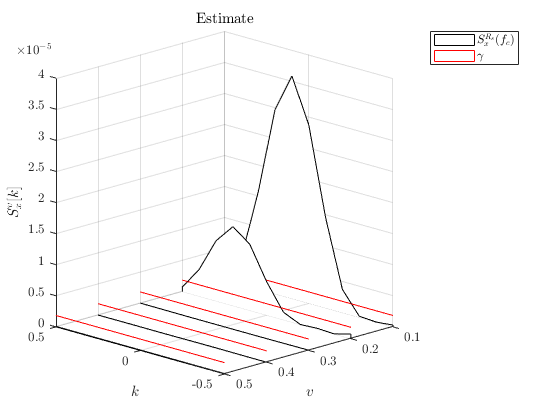

% valid alpha range is [0 Fs/2]
a_step  = min(Rs);
a_array = (Rs:a_step:Fs/2)';

% valid fc range is [-Fs/2 Fs/2]
fc_step  = min(fc);
fc_array = (-Fs/2:fc_step:Fs/2)';

sca_tuples = sca_detect(agc, a_array, fc_array, Fs, beta);


% 1:a, 2:fc, 3:S
detects = 0;
false_alarms = 0;
Pd = 0;
Pfa = 0;
if isempty(sca_tuples) == 0
    for idx_sca = 1:length(sca_tuples(:,1))
        disp("detected waveform:")
        disp(["Rs:" a_array(sca_tuples(idx_sca,1))/1e6 "MBd"])
        disp(["fc:" fc_array(sca_tuples(idx_sca,2))/1e6 "MHz"])
        disp(["Co:" sca_tuples(idx_sca,3)]) % correlation strength
        
        % check how many accurate detects there were
        % just worrying about Rs, doesnt check for fcs
        if ismember(sca_tuples(idx_sca,1)*a_step, Rs)
            detects = detects + 1;
        else
            false_alarms = false_alarms + 1;
        end
        
    end  


  % this is fine bc we don't count correct rejects or misses  
  Pd  = detects/length(Rs);  
  Pfa = false_alarms/(length(a_array)-length(Rs));
end

detected waveform:


    "Rs:"    "0.1"    "MBd"



    "fc:"    "0.1"    "MHz"



    "Co:"    "3.5793e-05"



detected waveform:


    "Rs:"    "0.2"    "MBd"



    "fc:"    "0.2"    "MHz"



    "Co:"    "1.2702e-05"

